
% z t r
% PF 30kV vacuum
date = 230125;
shot_num = 2;
low_n_folder = strcat('C:\Users\uswk0\OneDrive\ドキュメント\GitHub\test-open\道家\卒論\data\',num2str(date),'/');

raw_signal = read_datafile(shot_num,low_n_folder);




calib_coefficient = zeros(1,24);
% probe positionによるベクトル方向
direction = ...
   [1,1,1,1,1,1,...
    -1,1,1,-1,1,1,...
    1,1,1,-1,1,1,...
    1,1,1,1,1,1];
for i = 1:8
    calib_coefficient((i-1)*3+1:(i-1)*3+3) = [37.7,41.6,133]*10^-6;
end
RC_data = RC_calibration(24);

% rearrange to 1-24 in channel number according to labels on cable
B(:,1:24) = raw_signal(:,2:25)./calib_coefficient.*direction.*transpose(RC_data);

%toroidal_mode_B = toroidal_mode_raw(:,2:25)*1000;
time_array = raw_signal(:,1);


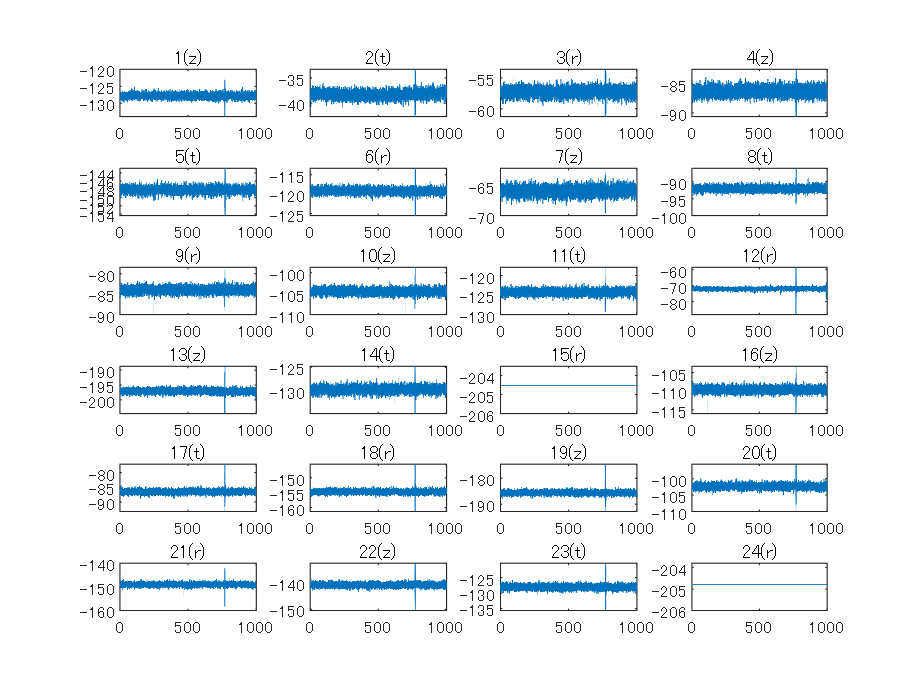

% check all V signals 
% raw signal [mV]
for i = 1:24
    subplot(6,4,i)
    plot(time_array, raw_signal(:,i+1)*10^3);
    %xlabel('us');
    %ylabel('mV')
    
    %xlim([760 800])
   % ylim([-50 50]);
    component_all = ['r','z','t'];
    component = component_all(rem(i,3)+1);
    title([num2str(i),'(',component,')'])
end